%user input for varience and mean of stock A and B
mean_A = input('Mean of Stock A: ');
mean_B = input('Mean of Stock B: ');
var_A = input('Varience of Stock A: ');
var_B = input('Varience of Stock B: ');
covab = input('Cov of stock:');
corr_coff = input('Correlation Coefficient: ');

if isempty(covab)
    covab = corr_coff*sqrt(var_A)*sqrt(var_B)
end

covab = 1.0976e-04


if isempty(corr_coff)
    corr_coff = covab/(sqrt(var_A)*sqrt(var_B))
end

stock = {"A"; "B"};
Mean = [mean_A; mean_B];
Varience = [var_A; var_B];
T = table(stock,Mean, Varience)

T = 2×3 table
     stock        Mean         Varience 
    _______    ___________    __________

    {["A"]}    -0.00042532    0.00018185
    {["B"]}      0.0020097     0.0028231




% Assumming that A has weight Alpha, B has weight 1-(alpha)
syms 'alpha';
Var_portfolio = simplify(expand(alpha^2*(var_A) + (1-alpha)^2*(var_B) + 2*(alpha)*(1-alpha)*corr_coff*sqrt(var_A)*sqrt(var_B)))

$$Var\_portfolio = \frac{521074655905551952431631721152452377072436457111\,\alpha^{2}}{187072209578355573530071658587684226515959365500928}-\frac{1015177445804497412715865306588798658979338858135\,\alpha }{187072209578355573530071658587684226515959365500928}+\frac{6509609258410115}{2305843009213693952}$$

%Find P when shortselling is not allowed. 
minimum_sd = simplify(solve(diff(Var_portfolio, alpha), alpha))

$$minimum\_sd = \frac{1015177445804497412715865306588798658979338858135}{1042149311811103904863263442304904754144872914222}$$

%idk work in progress

syms 'mean' 'mu_p' a;
mean = a*(mean_A) + (1-a)*(mean_B);
alpha = solve(mean == 'mu_p' ,a)

$$alpha = \frac{37072735159583336}{44918467455525335}-\frac{18446744073709551616\,\mu_{p}}{44918467455525335}$$

one_minus_alpha = 1- solve(mean == 'mu_p' ,a)

$$one\_minus\_alpha = \frac{18446744073709551616\,\mu_{p}}{44918467455525335}+\frac{7845732295941999}{44918467455525335}$$

Var_portfolio = simplify(expand(alpha^2*(var_A) + (one_minus_alpha)^2*(var_B) + 2*(alpha)*(one_minus_alpha)*corr_coff*sqrt(var_A)*sqrt(var_B)))

$$Var\_portfolio = \frac{521074655905551952431631721152452377072436457111\,{\mu_{p}}^{2}}{1109225108524511263788156966534058838117580800}+\frac{6964889627437562657819864772017911611234647573740186357874745633\,\mu_{p}}{20461591697084362398767266392836898281944649467124010254650572800}+\frac{11401203956368980757259401806722523458416819143154107613390987763698940632158107}{47181218172106941114380315708356386664388282184014236771614756854130362480695705600}$$

coeff = flip(coeffs(Var_portfolio));
complete_the_square = simplify(coeff(1)*(('mu_p' + coeff(2)/(2*coeff(1))))^2 + coeff(3) - (coeff(2)^2)/(4*coeff(1)))

$$complete\_the\_square = \frac{521074655905551952431631721152452377072436457111\,{\left(\mu_{p}+\frac{6964889627437562657819864772017911611234647573740186357874745633}{19224261641571968580932417442215218066872624546792493180606849482752}\right)}^{2}}{1109225108524511263788156966534058838117580800}+\frac{70179222627946205647469610324669375487513410866120739018452827384486296785030151852149432869615}{389914348942131722295554031936756681207362364498875826741871795729989746999803075367930976410796032}$$



%asymptope remember to + - lmao
asymptope = simplify(sqrt(complete_the_square - (coeff(3) - (coeff(2)^2)/(4*coeff(1)))))

$$asymptope = \frac{\sqrt{1716499646124810811136313601027193785498049196137228077308805094815421253744542}\,\sqrt{{\left(19224261641571968580932417442215218066872624546792493180606849482752\,\mu_{p}+6964889627437562657819864772017911611234647573740186357874745633\right)}^{2}}}{1162067615273408394294328404186895537953578044916838552892784777335119672209360667113702098421463667179520}$$


%answers are below
GMPV_mean = simplify(solve(diff(Var_portfolio)))

$$GMPV\_mean = -\frac{6964889627437562657819864772017911611234647573740186357874745633}{19224261641571968580932417442215218066872624546792493180606849482752}$$

GMPV_sd= simplify(sqrt(coeff(3) - (coeff(2)^2)/(4*coeff(1))))

$$GMPV\_sd = \frac{\sqrt{73137228565152389074370227500025230122337122461944719141414651075695631584857232175548721567566746513301509215066156878139554864155681205164530}}{20158099375072968526719790551888264499689029156777485329348007803226161152}$$

Weight_vector = [simplify(subs(alpha, 'mu_p', GMPV_mean));simplify(subs(one_minus_alpha, 'mu_p', GMPV_mean))]

$$Weight\_vector = \left(\begin{array}{c} \frac{1015177445804497412715865306588798658979338858135}{1042149311811103904863263442304904754144872914222}\\ \frac{26971866006606492147398135716106095165534056087}{1042149311811103904863263442304904754144872914222} \end{array}\right)$$

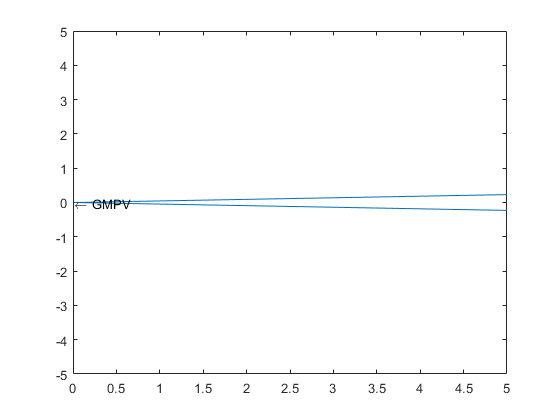


%add graphing is sus
% this graph sus as hell dont trust it plot on own
fplot(sqrt(complete_the_square), mu_p)
xlim([0 5])
text(GMPV_sd, GMPV_mean, '\leftarrow GMPV')